% Define parameters
N = 500; % Number of observations
Fs = 50; % Sampling frequency (Hz)

f1 = 10; % Frequency 1 (Hz)
f2 = 17; % Frequency 2 (Hz)

missing_percentage = 0.1; % Percentage of missing data (10%)

target_snr = 10; % Target Signal-to-Noise Ratio (SNR)

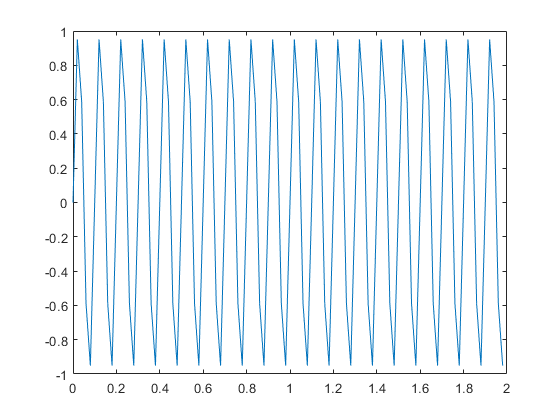

% Generate time vector
t = (0:N-1)'/Fs;
signal1 = sin(2*pi*f1*t);
plot(t(1:100), signal1(1:100))

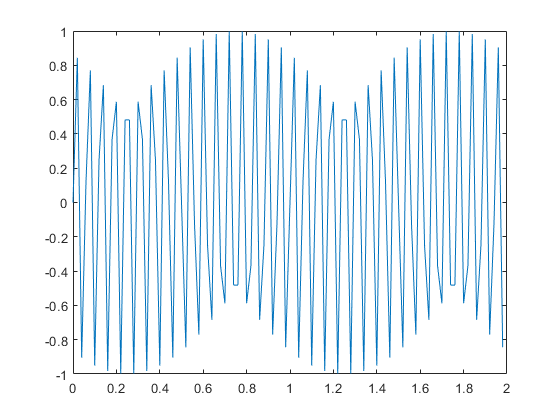

signal2 = sin(2*pi*f2*t);
plot(t(1:100), signal2(1:100))

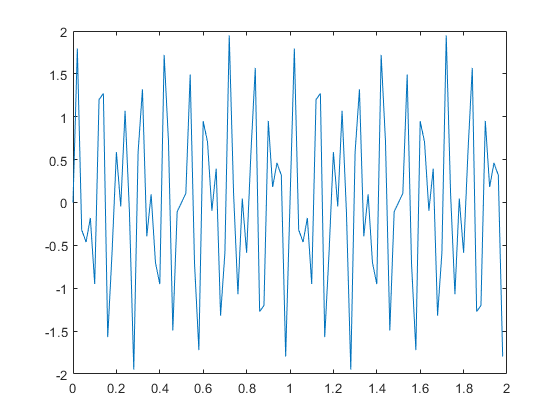

% Generate signal (sum of two sines)
signal =  signal1 + signal2;
plot(t(1:100), signal(1:100))

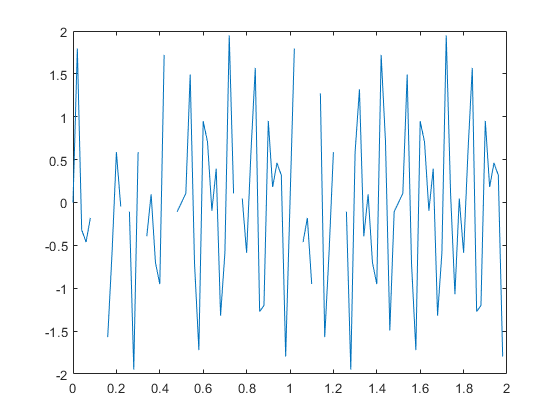


% Randomly sample the signal with missing data
missing_indices = sort(randperm(N, round(N*missing_percentage)));
missing_signal = signal;
missing_signal(missing_indices) = nan;
plot(t(1:100), missing_signal(1:100))

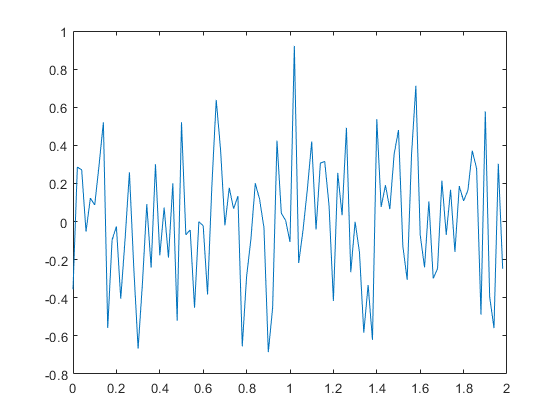


% Calculate signal power
signal_power = sum(signal.^2)/N;
% Calculate noise power for target SNR
noise_power = signal_power / (10^(target_snr/10));
% Generate noise
noise = sqrt(noise_power) * randn(size(missing_signal));
plot(t(1:100), noise(1:100))

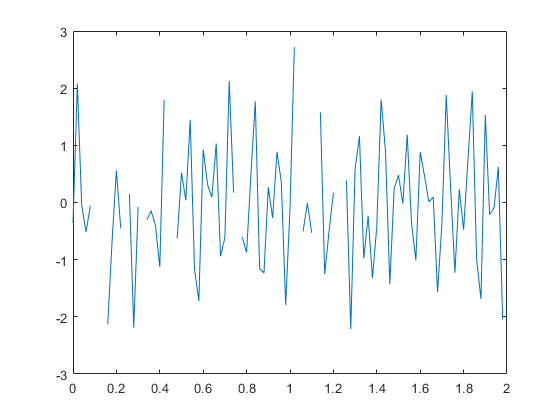


% Add noise to the missing signal
noisy_signal = missing_signal + noise;
plot(t(1:100), noisy_signal(1:100))

mean(noisy_signal)

ans = NaN

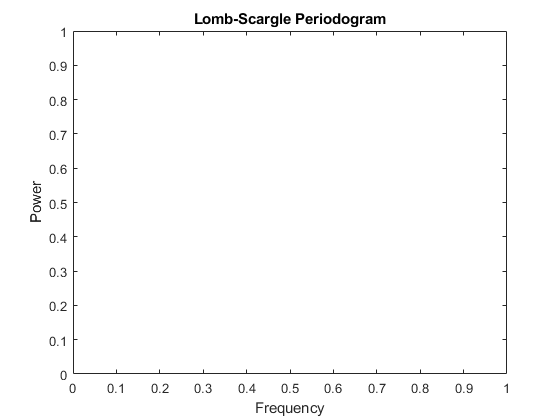

learning_rate = 0.001;
epochs = 100;
[power, frequency] = lsp(t, noisy_signal, learning_rate, epochs);
% Plot the Lomb-Scargle periodogram
plot(frequency, power);
xlabel('Frequency');
ylabel('Power');
title('Lomb-Scargle Periodogram');

power

power =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


frequency

frequency =          0    0.1004    0.2008    0.3012    0.4016    0.5020    0.6024    0.7028    0.8032    0.9036    1.0040    1.1044    1.2048    1.3052    1.4056    1.5060    1.6064    1.7068    1.8072    1.9076    2.0080    2.1084    2.2088    2.3092    2.4096    2.5100    2.6104    2.7108    2.8112    2.9116    3.0120    3.1124    3.2128    3.3132    3.4136    3.5140    3.6144    3.7148    3.8152    3.9156    4.0160    4.1164    4.2169    4.3173    4.4177    4.5181    4.6185    4.7189    4.8193    4.9197
